## Validate vector autoregressive model

**Load cascades**

[cascades, spikes] = load_cascades(emp_data_dir);

Analyzing DataSet01.mat...
Analyzing DataSet02.mat...
Analyzing DataSet03.mat...
Analyzing DataSet04.mat...
Analyzing DataSet05.mat...
Analyzing DataSet06.mat...
Analyzing DataSet07.mat...
Analyzing DataSet08.mat...
Analyzing DataSet09.mat...
Analyzing DataSet10.mat...
Analyzing DataSet11.mat...
Analyzing DataSet12.mat...
Analyzing DataSet13.mat...
Analyzing DataSet14.mat...
Analyzing DataSet15.mat...
Analyzing DataSet16.mat...
Analyzing DataSet17.mat...
Analyzing DataSet18.mat...
Analyzing DataSet19.mat...
Analyzing DataSet20.mat...
Analyzing DataSet21.mat...
Analyzing DataSet22.mat...
Analyzing DataSet23.mat...
Analyzing DataSet24.mat...
Analyzing DataSet25.mat...


**Train with all data**

nets = load_emp_nets(emp_data_dir);
As = cellfun(@(x) x.A, nets, 'UniformOutput', false);

**Calculate RMSE**

e = rmse(As, spikes);

Calculating rmse for network 1
Calculating rmse for network 2
Calculating rmse for network 3
Calculating rmse for network 4
Calculating rmse for network 5
Calculating rmse for network 6
Calculating rmse for network 7
Calculating rmse for network 8
Calculating rmse for network 9
Calculating rmse for network 10
Calculating rmse for network 11
Calculating rmse for network 12
Calculating rmse for network 13
Calculating rmse for network 14
Calculating rmse for network 15
Calculating rmse for network 16
Calculating rmse for network 17
Calculating rmse for network 18
Calculating rmse for network 19
Calculating rmse for network 20
Calculating rmse for network 21
Calculating rmse for network 22
Calculating rmse for network 23
Calculating rmse for network 24
Calculating rmse for network 25


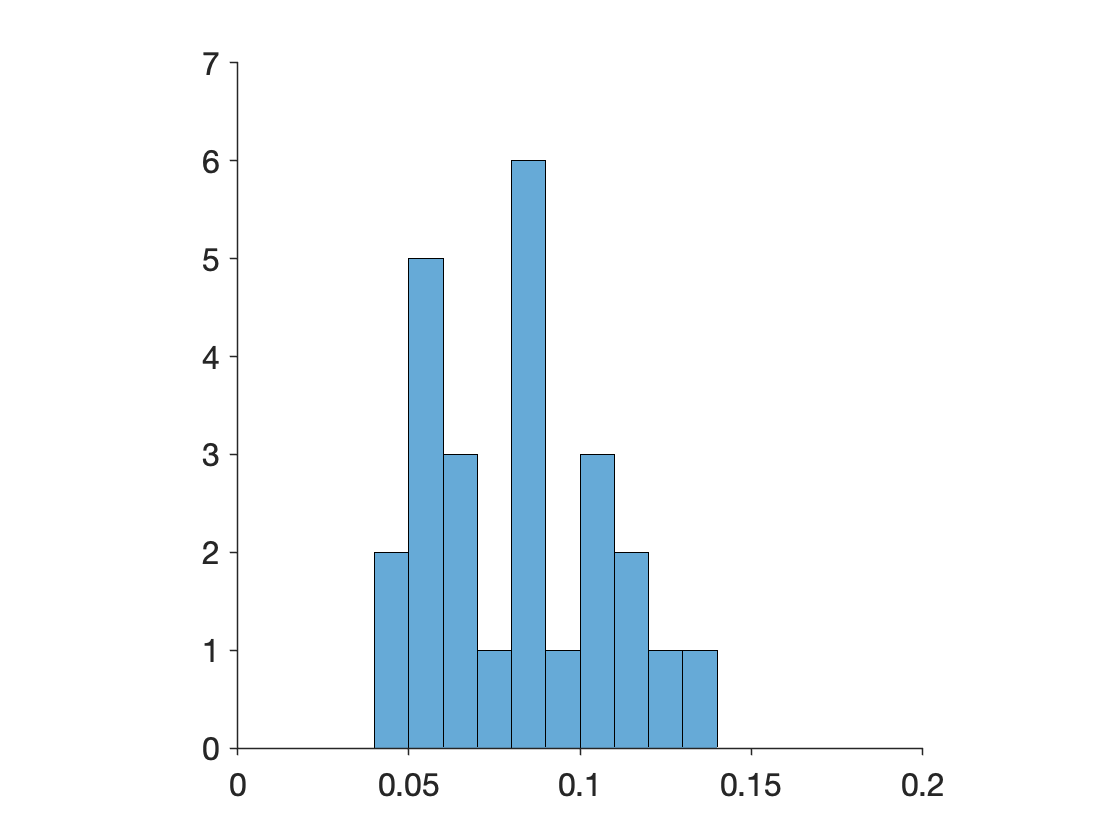

histogram(cellfun(@mean,e),10)
axis([0 .2 0 7])
prettify

**K-fold cross validation**

- Divide into k=20 folds.

- Generate k=20 training & testing sets.

k = 20;


durations = cellfun(@csc_durations, cascades, 'UniformOutput', false);

**Train models**

**Test models**

function e = rmse(model, data)
    e = cell(length(data),1);
    for i = 1 : length(data)
        disp(['Calculating rmse for network ' num2str(i)])
        x = data{i};
        xp = model{i} * x;
        e{i} = sqrt(mean((x-[x(:,1),xp(:,1:end-1)]).^2,2));
    end
end